# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.9 多张图片叠加显示

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)  [**自定义colormap**](https://zhuanlan.zhihu.com/p/489920741)

用颜色表示数值大小

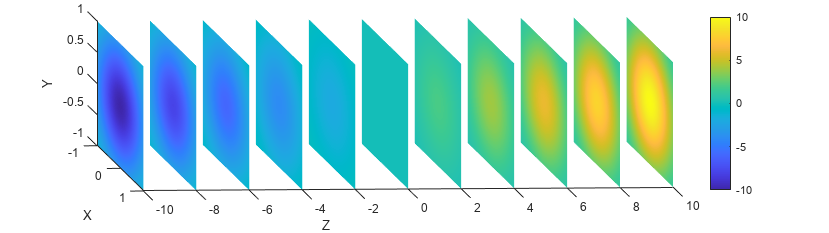

clear;clc;
x = linspace(-1, 1, 21);
y = linspace(-1, 1, 21);
z = linspace(-10, 10, 11);
[X, Y] = meshgrid(x, y);
hold on
for i = 1 : length(z)
    Z = z(i)*ones(size(X));
    % 颜色
    C = exp(-(X.^2 + Y.^2)) .* Z;
    surf(X, Z, Y, C)
end
shading interp
xlabel("X");
zlabel("Y");
ylabel("Z");
colorbar;
view(85,20);
set(gcf, 'unit', 'normalized', 'position', [0.1, 0.1, 0.8, 0.4]);

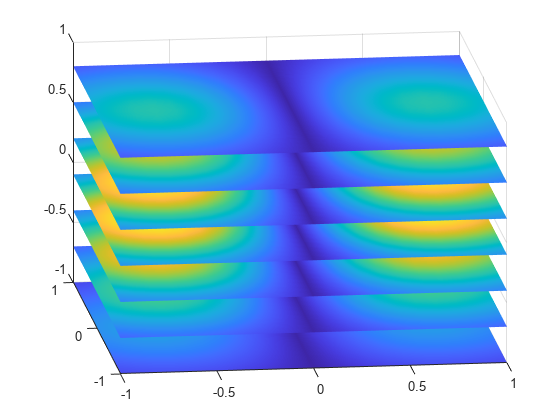


figure;
[X, Y, Z] = meshgrid(x);
V = abs(X.*exp(-X.^2-Y.^2-Z.^2));
% 哪个方向切片就改对应的
% plts = slice(X, Y, Z, V, -1:0.3:1, [], []);
plts = slice(X, Y, Z, V, [], [], -1:0.3:1);
shading interp
view([-7, 21])